% % Parametri
% Ts = 0.1; % Tempo di campionamento
% p = pi/4; % Valore esemplificativo per p
% 
% % Matrici dello spazio di stati
% A = [1 0 Ts*cos(p) 0;
%      0 1 Ts*sin(p) 0;
%      0 0      1    0;
%      0 0      0    1];
% 
% B = [cos(p)*Ts^2/2   ,   0;
%     sin(p)*Ts^2/2    ,   0;
%     0               ,   0;
%     0               ,   0];
% % 
% % Stati iniziali
% xk = ones(4,1);
% 
% Vettore di ingresso (da definire in base al sistema)
% wk = zeros(2,1);
% 
% Calcolo del prossimo stato
% xk_plus_1 = A*xk + B*wk;
% 
% disp('Prossimo Stato:');
% disp(xk_plus_1);




% Generazione di dati casuali
num_points = 50;
x_data = linspace(-160,-155,50); % Coordinate x tra -5 e 5
y_data = linspace(20,23,50); 
v_data = sin(x_data) .* cos(y_data); % Velocità generata come funzione di x e y
p_data = atan2(y_data, x_data); % Heading generato come angolo polare
% conversione
% [x_data,y_data,utmzone]=deg2utm(x_data, y_data);
% [o_Lat, o_Lon]=utm2deg(x_data,y_data,utmzone);

Ts = 1;

state_vector=[x_data;y_data;v_data; p_data];
% state_vector=state_vector';
% Initialize the state history
x_hist = state_vector(:,1);
for index= 2:1:length(state_vector)
    w=rand(2,1);
    % Define the state transition matrix
    F_k=[1 0 Ts*cos(state_vector(4,index)) 0;
           0 1 Ts*sin(state_vector(4,index)) 0;
           0 0 1 0;
           0 0 0 1;];
    x_dot=F_k*state_vector(:,index);


    % Store the state history
    x_hist = [x_hist, x_dot];
end

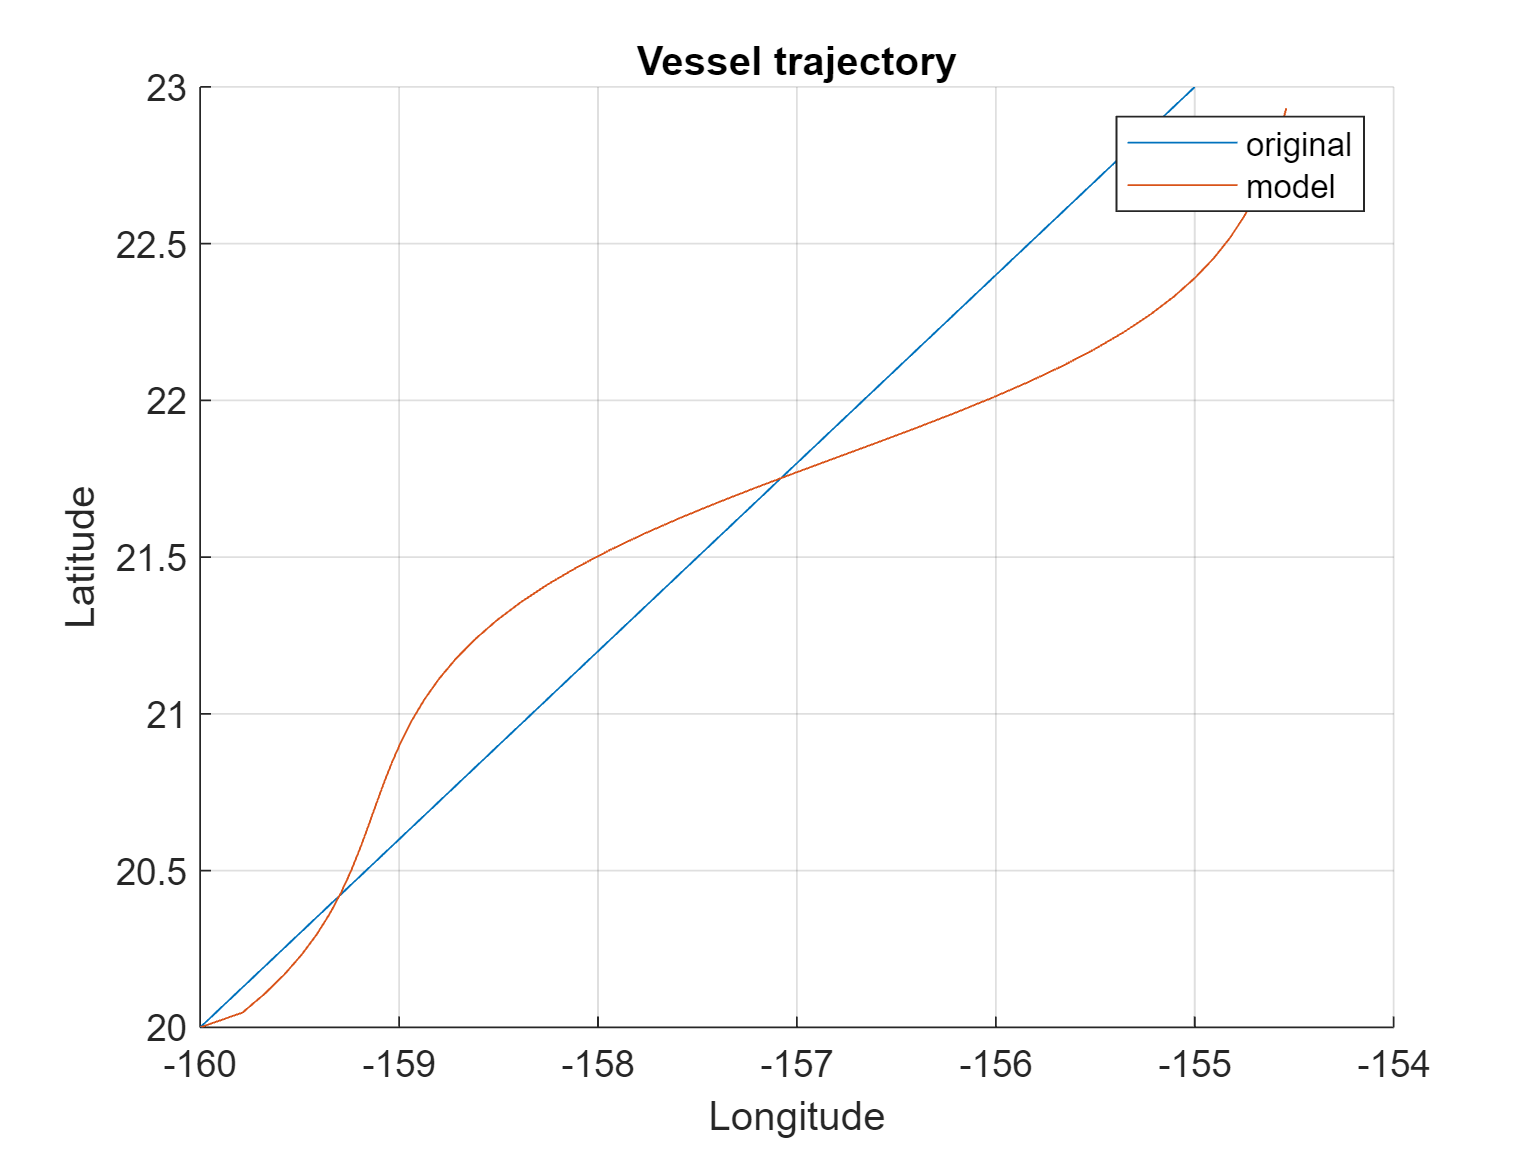


figure
hold on
plot(state_vector(1,:),state_vector(2,:))
plot(x_hist(1,:), x_hist(2,:))
xlabel('Longitude')
ylabel('Latitude')
title('Vessel trajectory')
legend('original','model') %%viene sbagliata perchè non converto LAT e LON in UTM ZONE
grid on

FUNZIONI BASE$\bigotimes$

[X, Y] = meshgrid(min(x_data):1:max(x_data), min(y_data):1:max(y_data));
grid = [X(:) Y(:)];


% Parametro sigma
sigma = 1.0;

basis_functions = cell(size(grid, 1), 1);
sigma = 1; % Definisci il valore di sigma qui

for i = 1:size(grid, 1)
    x_i = grid(i, 1);
    y_i = grid(i, 2);
    basis_functions{i} = @(x, y,p) exp(-((x - x_i).^2 + (y - y_i).^2 + (sin(p) - sin(0)).^2 + (cos(p) - cos(0)).^2) / (2 * sigma^2));
end

state_vector=[x_data;y_data;v_data; p_data];
% state_vector=state_vector';
% Initialize the state history
x_hist = state_vector(:,1);
for index= 2:1:length(state_vector)
    w=rand(2,1);
    % Define the state transition matrix
    F_k=[1 0 Ts*cos(state_vector(4,index)) 0;
           0 1 Ts*sin(state_vector(4,index)) 0;
           0 0 1 0;
           0 0 0 1;];
     G_k=[cos(state_vector(4,index))*Ts^2/2 0;
          sin(state_vector(4,index))*Ts^2/2 0;
              Ts 0;
               0 Ts;];
    
     % Evaluate the radial basis functions (RBFs) at this time step
    basis_eval = diag(zeros(size(grid, 1), 1));
    for i = 1:size(grid, 1)
        basis_eval(i,i) = basis_functions{i}(state_vector(1,index), state_vector(2,index), state_vector(4,index));
    end

    x_dot=F_k*state_vector(:,index);


    % Store the state history
    x_hist = [x_hist, x_dot];
   end

[F_k*state_vector(:,index)+ G_k*ones(2,1);
    ones(length(grid),1)]



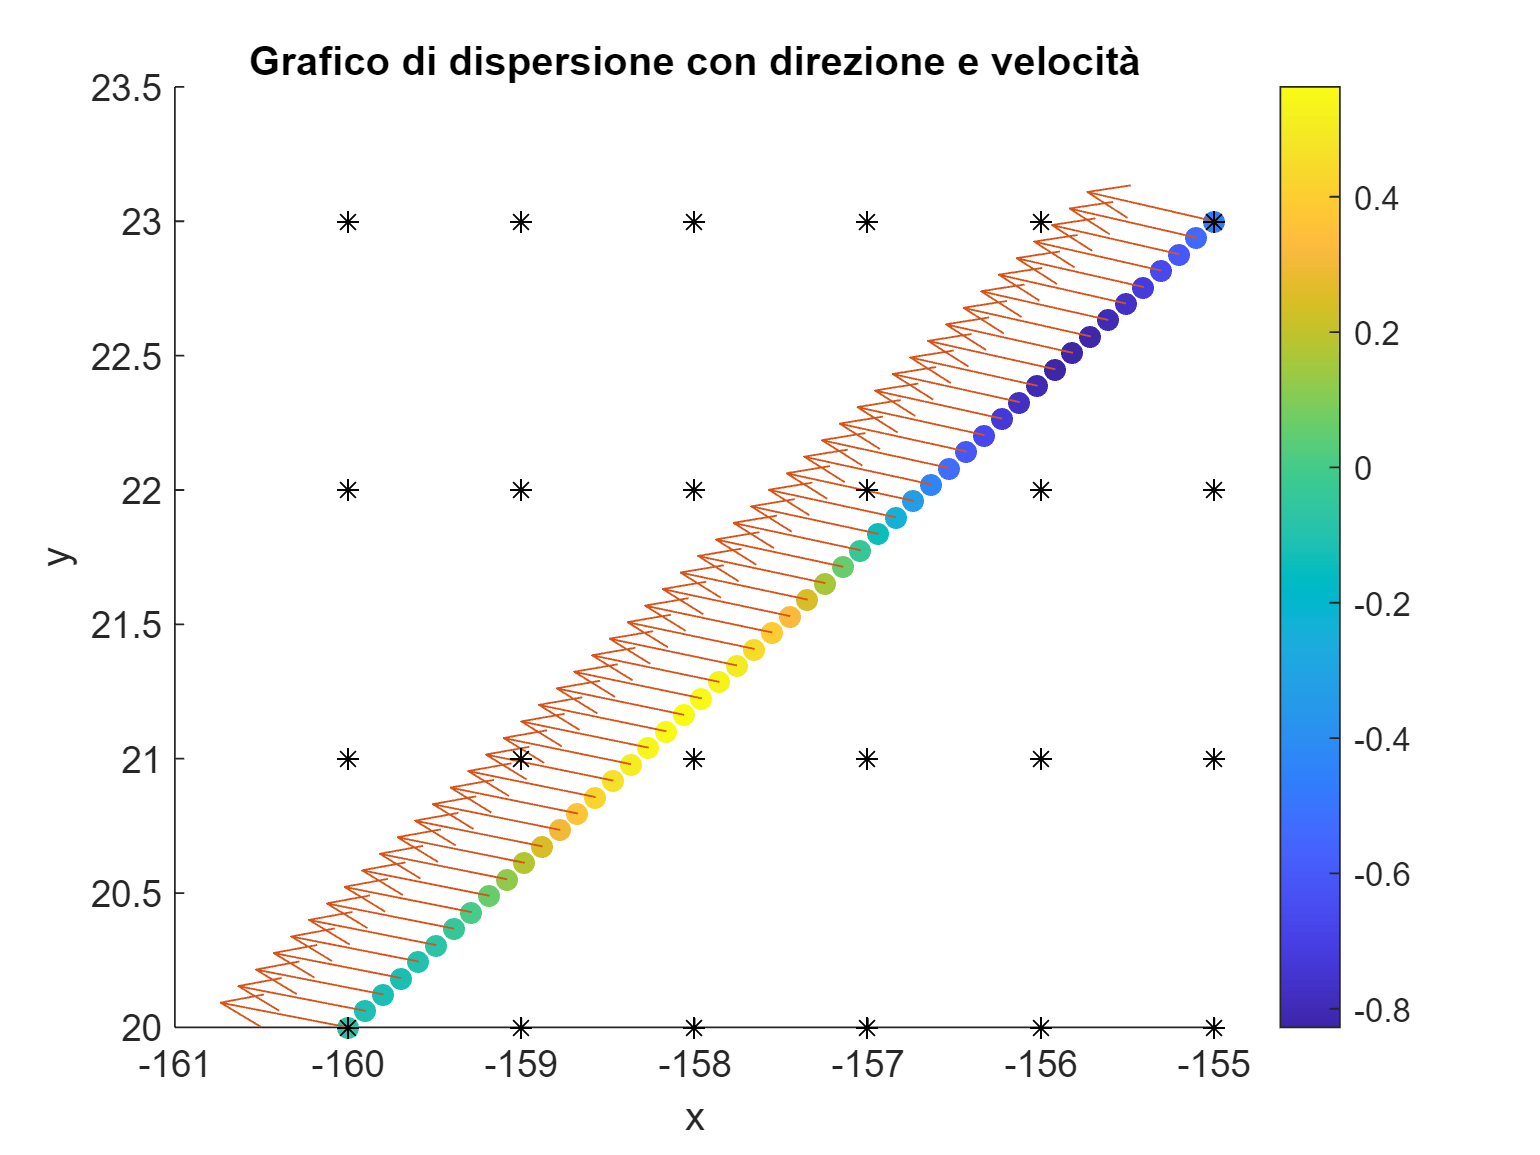

% Calcolo delle componenti del vettore di direzione
u = cos(p_data);
v = sin(p_data);
% Creazione del grafico
figure
grid on
scatter(x_data, y_data, 36, v_data, 'filled') % Grafico di dispersione con l'intensità del colore proporzionale alla velocità
hold on
quiver(x_data, y_data, u, v) % Campo di vettori per la direzione del heading
scatter(X, Y, '*k') % Grafico di dispersione con l'intensità del colore proporzionale alla velocità

colorbar% Barra del colore per la velocità
title('Grafico di dispersione con direzione e velocità')
xlabel('x')
ylabel('y')